HW7

format long
int = integral(@(x)cos(2.*x).*exp(-x),0,2*pi);

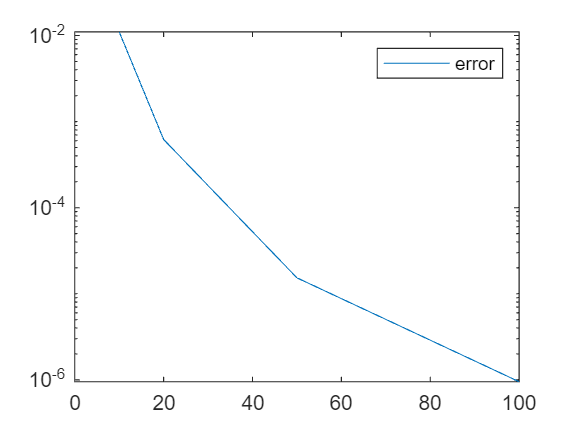

a = 0;
b=2*pi;
f = @(x)cos(2.*x).*exp(-x);
syms x

n=[10,20,50,100];
abs_error = zeros(1,4);
for i = 1:length(n)
    abs_error(i)=abs(int-composite_simpsons(f,a,b,n(i)));

end
semilogy(n,abs_error)
legend('error');

Using Adaptive Simpsons

Tol = 5 * 10^-5;
N = 10;
Adaptive_Simpsons(f,a,b,Tol,N)

ans =    0.199628938362467


Functions

function [S] = Simpsons(f,a,b)
h = (b-a)/2;
S = (h/3) * (f(a)+4*f((a+b)/2)+f(b));
end

function [AS] = Adaptive_Simpsons(f,a,b,Tol,N)
err=Simpsons(f,a,(a+b)/2)+Simpsons(f,(a+b)/2,b)-Simpsons(f,a,b);
if abs(err) <= 10*Tol || N==0
    AS=Simpsons(f,a,(a+b)/2)+Simpsons(f,(a+b)/2,b)+err/10;
else
    l_s = Adaptive_Simpsons(f,a,(a+b)/2,Tol/2,N-1);
    r_s = Adaptive_Simpsons(f,(a+b)/2,b,Tol/2,N-1);
    AS = l_s + r_s;
end
end

function [CS] = composite_simpsons(f,a,b,n)
h= (b-a)/n;
x = a:h:b;
F= f(x);
CS =  sum(h/3*(F(1:2:end-2)+4*F(2:2:end-1)+F(3:2:end)));
end